# ECE 101 - Assignment 6 - Numerical Analysis

Michael Dekoski

5-15-23

% Clear Workspace/Command Window
clear
clc

Start Timer

startTime = clock();

## Polynomials

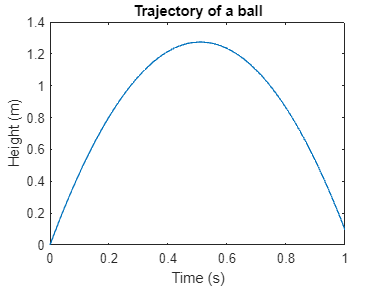

% Define a polynomial that represents the trajectory of a ball thrown upwards 
% with initial speed v0 and subject to gravity
v0 = 5; % initial speed
g = -9.81; % gravity constant
p = [0.5*g, v0, 0]; % coefficients of the polynomial: 0.5*g*t^2 + v0*t

% 1) Plot the polynomial
t = linspace(0, 1, 100); % time range of interest: from 0 to 1 second
y = polyval(p, t);
plot(t, y);
title('Trajectory of a ball');
xlabel('Time (s)');
ylabel('Height (m)');


% 2) Find the roots of the polynomial
roots_p = roots(p);
disp('The roots of the polynomial are:');

The roots of the polynomial are:


disp(roots_p);

         0
    1.0194




% 3) Apply a convolution to this polynomial
conv_p = conv(p, [1, -1]); % convolve with the polynomial x-1
disp('The resultant polynomial after convolution is:');

The resultant polynomial after convolution is:


disp(conv_p);

   -4.9050    9.9050   -5.0000         0



## Best Fit and Interpolation

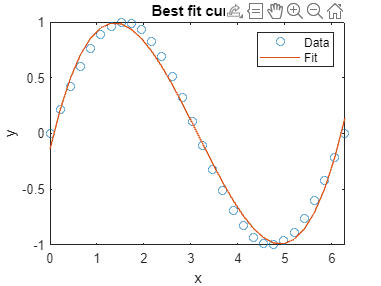

% 1) Load or create a data set
x = linspace(0, 2*pi, 30);
y = sin(x);

% 2) Best fit curve
p_fit = polyfit(x, y, 3); % fit a cubic polynomial to the data
y_fit = polyval(p_fit, x);
plot(x, y, 'o', x, y_fit);
title('Best fit curve');
xlabel('x');
ylabel('y');
legend('Data', 'Fit');

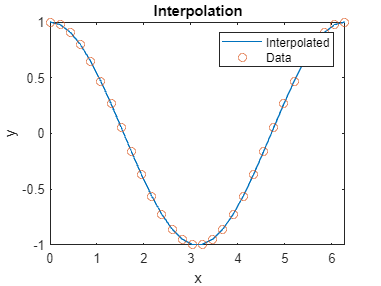


% 3) Create another data set
x_new = linspace(0, 2*pi, 30);
y_new = cos(x_new);

% 4) Interpolated line
y_inter = interp1(x_new, y_new, x, 'pchip'); % use cubic spline interpolation

% 5) Plot
plot(x, y_inter, x_new, y_new, 'o');
title('Interpolation');
xlabel('x');
ylabel('y');
legend('Interpolated', 'Data');

## Non-Polynomial Functions

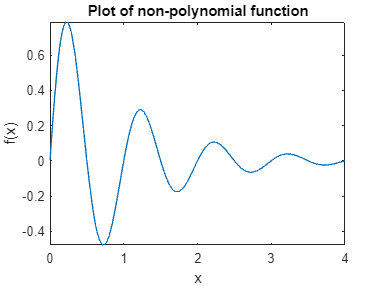

% 1) Choose a non-polynomial equation
f = @(x) exp(-x) .* sin(2*pi*x);

% 2) Plot the function
fplot(f, [0, 4]);
title('Plot of non-polynomial function');
xlabel('x');
ylabel('f(x)');


% 3) Find a zero crossing or a minimum or maximum point
options = optimset('Display','off');
x_zero = fzero(f, 3.25, options); % initial guess at 0.5
disp('The zero crossing is at x = ');

The zero crossing is at x = 


disp(x_zero);

     3



## Stop Timer

% End time
stopTime = clock();

Calculate elapsed time

% vector into seconds
startSec = startTime(6) + (startTime(5)*60) + (startTime(4)*3600);
stopSec = stopTime(6) + (stopTime(5)*60) + (stopTime(4)*3600);

dayDiff = stopTime(3) - startTime(3);
dayInSec = dayDiff * 86400;
timeInHours = (stopSec - startSec + dayInSec)/3600;
hour = floor(timeInHours)

hour = 0

hourRem = timeInHours - hour;
timeInMinutes = hourRem * 60;
min = floor(timeInMinutes)

min = 0

minRem = timeInMinutes - min;
sec = minRem * 60

sec = 0.8290